Read the .wav file (replace file_name by your group’s file

Variable x stores the wave and fs stores the sampling rate

[x, fs]=audioread('/Users/madelinelebreton/Documents/SCHOOL/3DX4/L03_Group11.wav');

Perform FFT on the original signal to determine the frequency of the \noise"

L=length(x);
NFFT=2^nextpow2(L);
X=fft(x,NFFT)/fs;

Show the sampling rate

fs

fs = 8000

We know the sampling rate is 8000 Hz

We need now to plot our FFT to find the source of the noise.

Plot single-sided amplitude spectrum

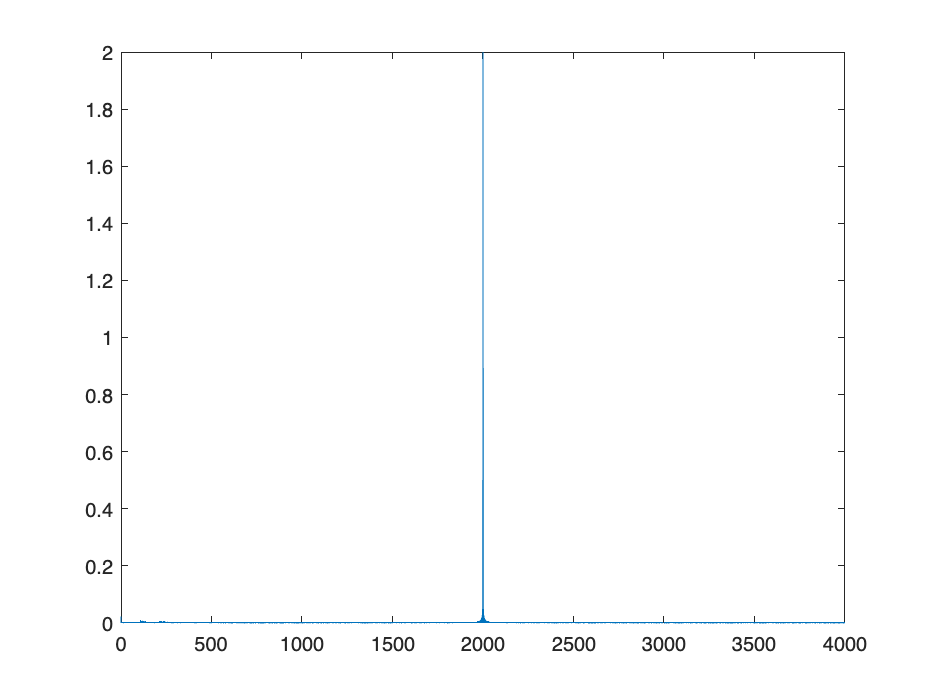

f=fs/2*linspace(0,1,NFFT/2+1);
plot(f,2*abs(X(1:NFFT/2+1)))

Reading the FFT we realize that the frequency we want to remove is 2000 Hz

(Hint: our noise is a pure sine wave)

Now specify the frequency you want to eliminate by setting

fkill = 0.5;

Determine the coefficients of the FIR filter that will remove that frequency.

Start off the following blank with the value 4, to numbers larger than 160.

Note: the following filter only works with EVEN numbers. 

`coeff = firgr(order, frequency_bands, desired_gain, weighting_types) -> larger order gives sharper notch`

coeff=firgr(120,[0,fkill-0.1, fkill, fkill+0.1, 1], [1,1,0,1,1],{'n', 'n', 's', 'n', 'n'})

coeff =    -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0001   -0.0000   -0.0003    0.0000    0.0005   -0.0000   -0.0008    0.0000    0.0012   -0.0000   -0.0019    0.0000    0.0029   -0.0000   -0.0041    0.0000    0.0058   -0.0000   -0.0079    0.0000    0.0105   -0.0000   -0.0135    0.0000    0.0171   -0.0000   -0.0212    0.0000    0.0256   -0.0000   -0.0302    0.0000    0.0350   -0.0000   -0.0397    0.0000


Plot the filter and the frequency response of the designed filter to verify that it satisfies the requirements

freqz(coeff,1);

You should try different filter lengths in the firgr command and find out which one is the best. Filter length of 4 is terrible. Ideally, your filter should only filter out the noise while passing all other signals. Try increasing your filter length until you can achieve an adequate result. Be sure to plot (with freqz()) each time you create a new filter. If the filter length is too large, the filter will "blow up". 

Save these coefficients in a text file, You will need them when coding the FIR filter. Scale them to fit the 16-bit range of the board.

coeff*32768

ans = 1.0e+04 *

   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0001    0.0000    0.0001   -0.0000   -0.0002    0.0000    0.0005   -0.0000   -0.0009    0.0000    0.0015   -0.0000   -0.0025    0.0000    0.0041   -0.0000   -0.0063    0.0000    0.0094   -0.0000   -0.0135    0.0000    0.0189   -0.0000   -0.0258    0.0000    0.0343   -0.0000   -0.0444    0.0000    0.0561   -0.0000   -0.0693    0.0000    0.0838   -0.0000   -0.0991    0.0000    0.1148   -0.0000   -0.1302    0.0000


fid=fopen('/Users/madelinelebreton/Documents/SCHOOL/3DX4/3DX4_tutorial3_coefficients.txt','w');

If you make a typing error with the following for-end block, you need to start from the "for" line again.

"Write coefficient i to a file as a scaled integer with a C-style array index"

for i=1:length(coeff)
    fprintf(fid,'coeff[%3.0f]=%10.0f;\n',i-1,32768*coeff(i));
end
fclose(fid);

Filter the input signal x(t) using the designed FIR filter to get y(t)

y=filtfilt(coeff,1,x);

Perform FFT on the filtered signal to observe the absence of frequency of the "noise".

Y=fft(y,NFFT)/L;

Play the unfiltered sound

Multiply by 3 to make the volume 3 times louder.

sound(3*x,fs);

Pause 5 seconds. (this is only necessary if you run these commands as a script)

pause(5);

Play the filtered sound. If cannot hear, try to change "3" to a larger integer such as "10" in the following sound function. Be careful of the possible damage to your hearing!

sound(10*y,fs);

The secret code for your group is CGTA06

Create 2 plots to compare

The first plot shows the FFT of the original signal.

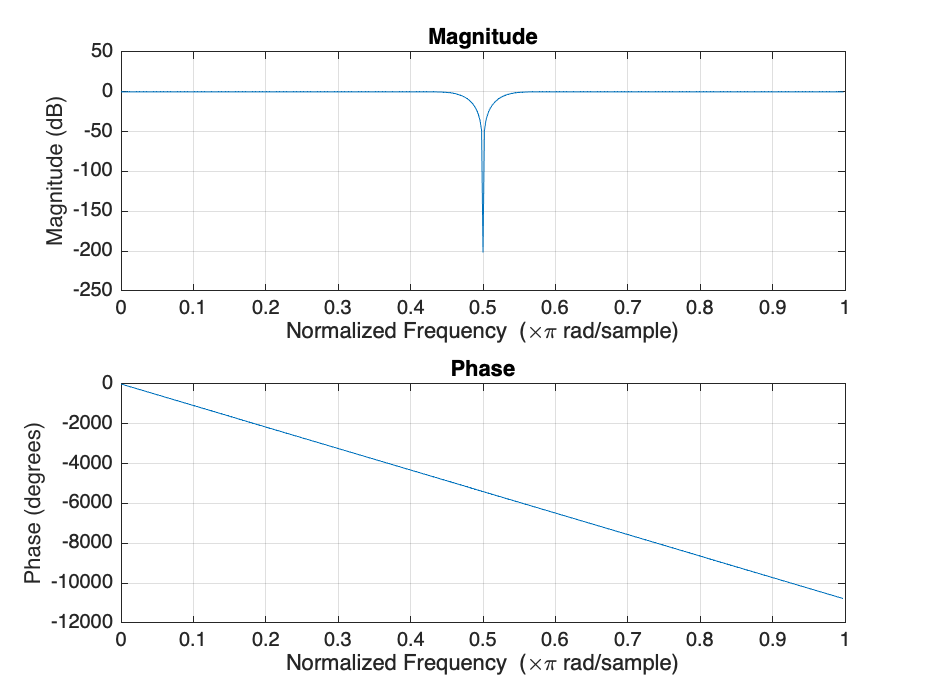

subplot(2,1,1);

plot(f,2*abs(X(1:NFFT/2+1)));
xlabel('frequency (Hz)');
ylabel('|X(f)|');
title('FFT of Original Sound')

The second plot shows the FFT of the filtered signal.

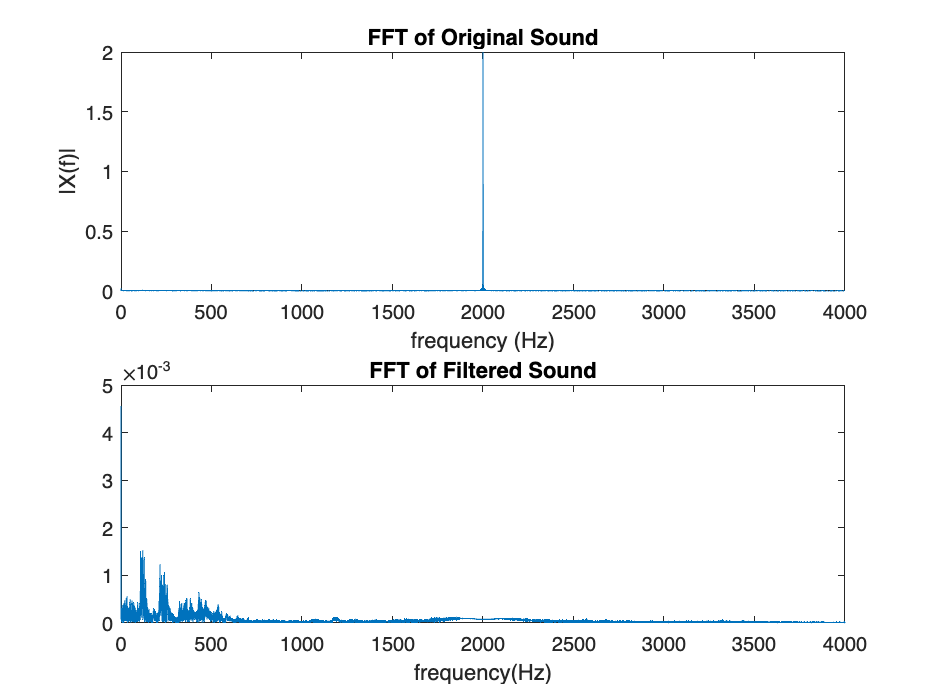

subplot(2,1,2);
plot(f, 2*abs(Y(1:NFFT/2+1)));
xlabel('frequency(Hz)');
title('FFT of Filtered Sound')

Write the filtered audio file to disk. If cannot hear anything when play the following .wav file, try to change "y" to "3*y", or with a larger integer, in the following function.

Be careful of the possible damage to your hearing when play the .wav file!

audiowrite('/Users/madelinelebreton/Documents/SCHOOL/3DX4/3DX4_tutorial3_filtered.wav',y*10,fs);